# WPI HPRC Flight Playback

Author: Daniel Pearson

Version: 5/12/2024

clear variables; close all; clc;

## Earth Constants

a_earth = 6378137.0;        % [m] Semi-major axis of Earth
% b_earth = 6356752.3142;     % [m] Semi-Minor axis of Earth
e_earth = 0.0818191908426;  % Eccentricity of Earth
b_earth = a_earth * sqrt(1 - e_earth^2);
r_earth = 6378137;          % [m] Radius of Earth
omega_earth = 7.2921159e-5; % Earth's rotation rate in radians per second
g = 9.81;                   % [m/s/s] Gravitational Acceleration

## Load Data

data = readtable('data.csv');

% time = data.Time(data.LON_DEG ~= 0);
% 
% for i = 1:length(data.Time)
%     time = data.Time(i);
%     utc(i,:) = round([2024, 2, 8, hours(time), mod(minutes(time), 60), mod(seconds(time),60)]);
% end
% 
% latNonZero = deg2rad(data.LAT_DEG(data.LAT_DEG ~= 0));
% lonNonZero = deg2rad(data.LON_DEG(data.LON_DEG ~= 0));
% altNonZero = deg2rad(data.ALT_MSL(data.LON_DEG ~= 0));
lat = data.gpsLat / 1e7;
lon = data.gpsLong / 1e7;
alt = data.gpsAltMSL / 1e2;

accelX = data.accelX * g;
accelY = data.accelY * g;
accelZ = data.accelZ * g;
timestamp = data.timestamp / 1e3;

## Plot Lat and Long

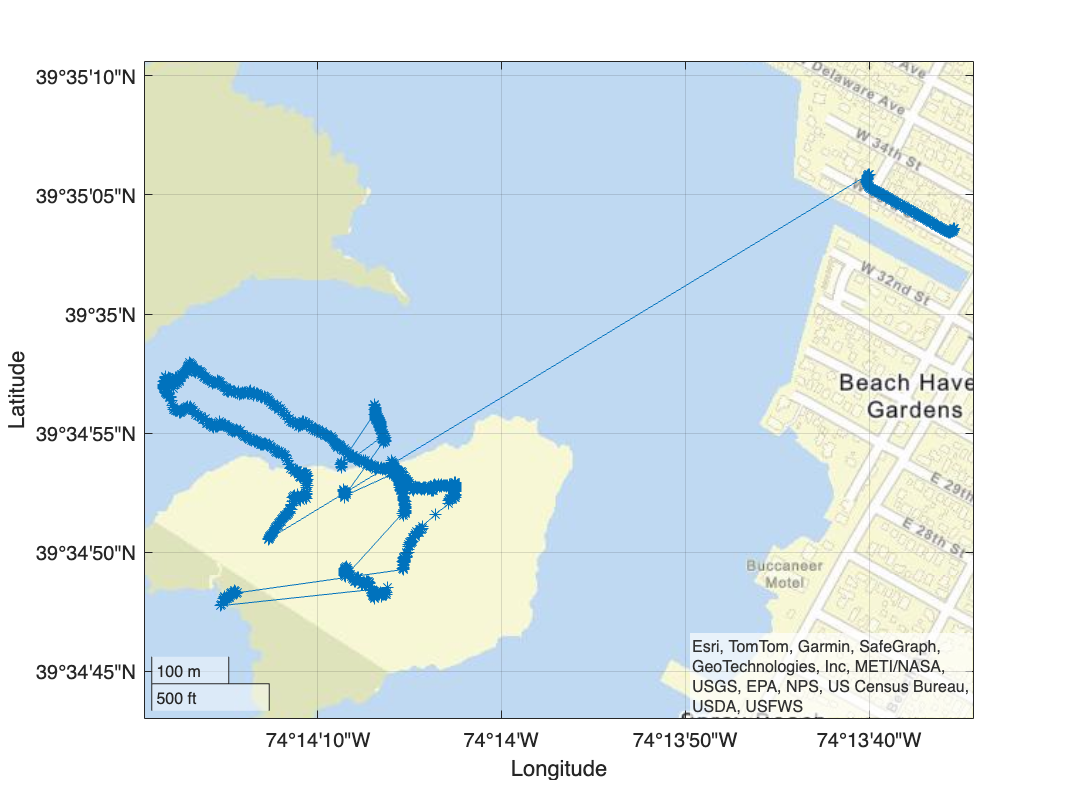

geoplot(lat, lon, '-*');
geobasemap streets;

## Plot Accel

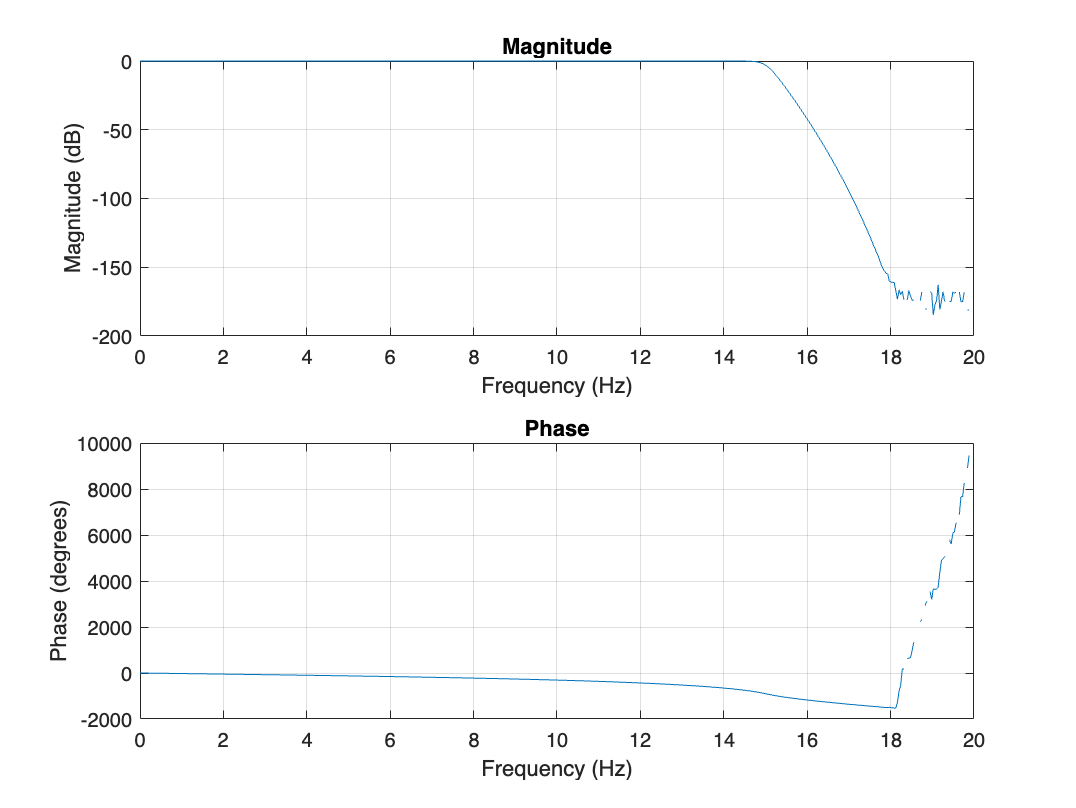

plot(timestamp, accelX);
title("Acceleration X")
ylabel("Acceleration (m/s/s)")
xlabel("Timestamp (s)")

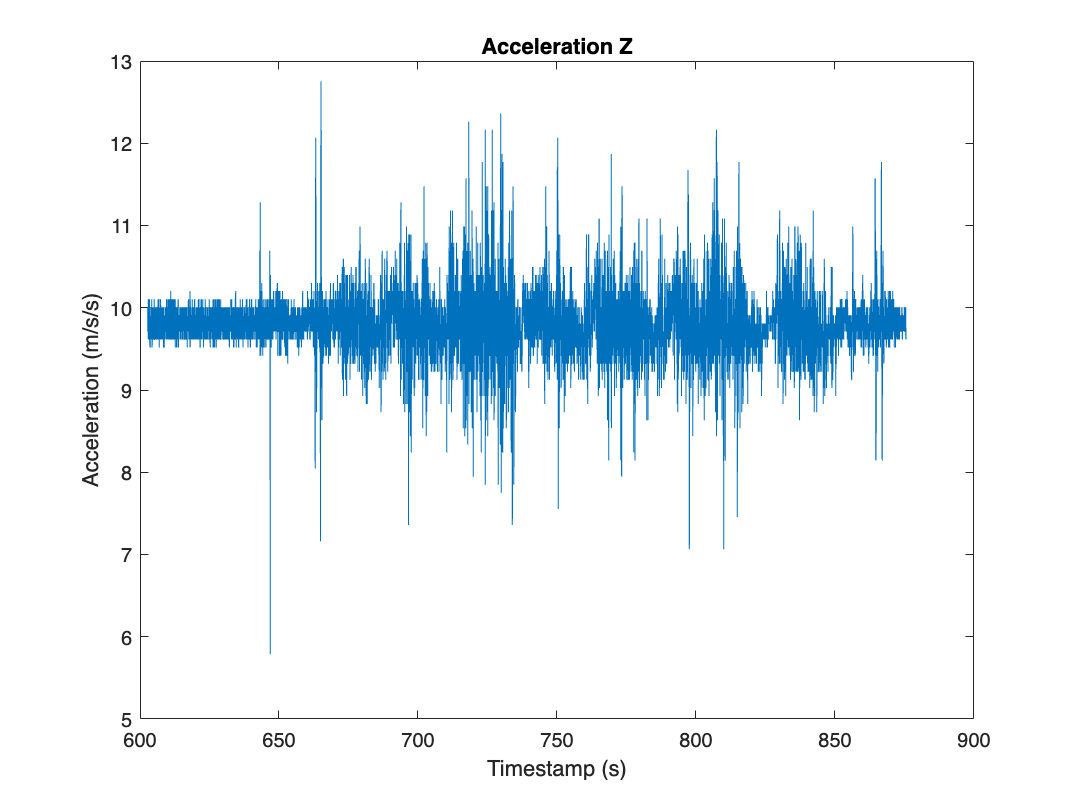


plot(timestamp, accelY);
title("Acceleration Y")
ylabel("Acceleration (m/s/s)")
xlabel("Timestamp (s)")

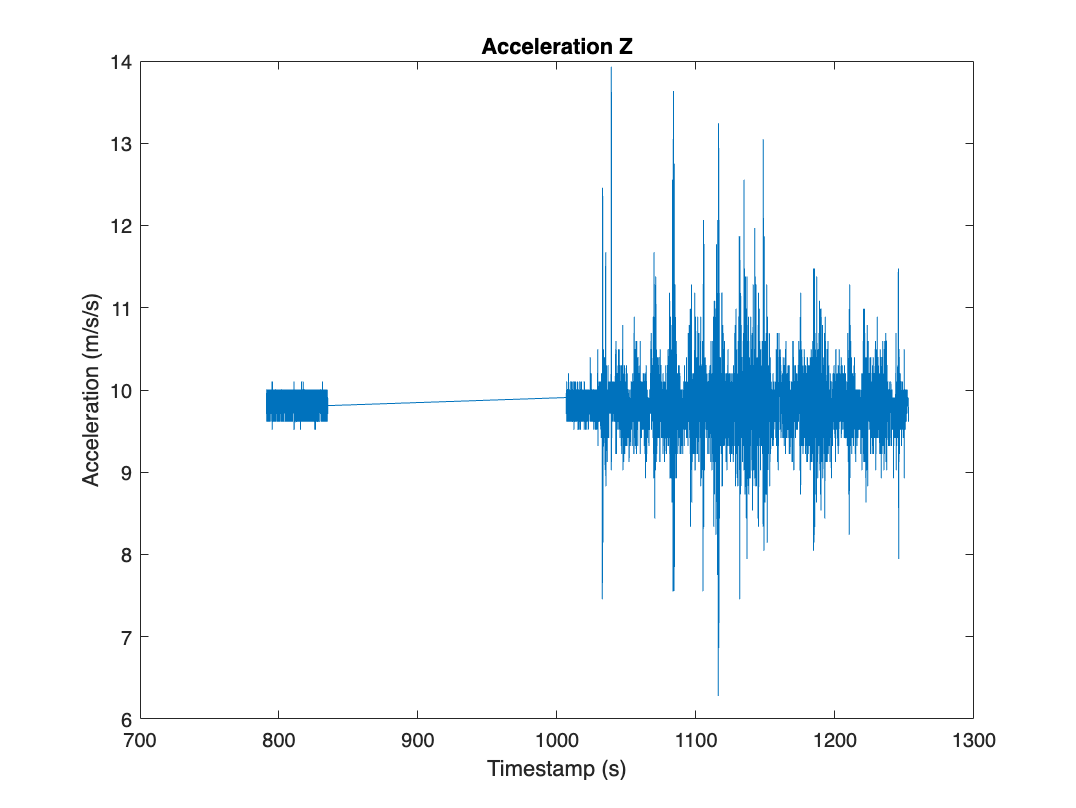


plot(timestamp, accelZ);
title("Acceleration Z")
ylabel("Acceleration (m/s/s)")
xlabel("Timestamp (s)")

## Plot Orientation

eul = quat2eul([data.w, data.i, data.j, data.k], "XYZ");